clear variables

% 构建较为准确的降阶分析模型
sysFull = load("Data\SimulateData\sysFull.mat");
sysFull = sysFull.sys;

[sysr, V, W]  = irka(sysFull,7);

IRKA step 005 - Convergence (combAny):  2.9e-02 8.2e-04 


sysDis = c2d(ss(sysr),0.02);

sysDis.B

ans = 1.0e+03 *

   -1.2261   -1.2180   -0.7723   -0.7754
   -0.4152   -0.4346   -0.2881   -0.2830
    0.0554    0.0425    0.0428    0.0313
    0.0928    0.1021    0.0465    0.0353
   -0.0082    0.0253   -0.0238   -0.0023
    0.0181    0.0160    0.0129    0.0112
    0.0167   -0.0064    0.0071   -0.0111


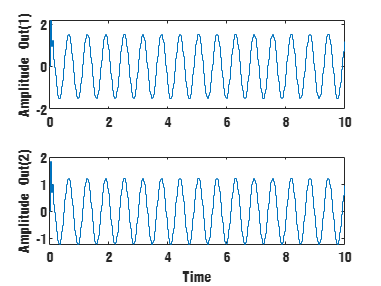

% 分析模型响应，并存储系统状态信息
u = @(t) [cos(10*t) * ones(1, 1);0*cos(2*t) * ones(1, 1);0*cos(3*t) * ones(1, 1); 0*cos(4*t) * ones(1, 1)];
figure
opts = struct('InputFcn', u, 'TimeRange', 10,'StoreStates',1);
[t,y,info] = ml_dt_ss_simulate(sysDis, opts);

Q = 1*eye(4);
R = 0.05*eye(2);

% Mx = Kk
[kalmf,L,~,Mx,Z] = kalman(sysDis,Q,R);

kalmf.InputGroup

ans = 包含以下字段的 struct :
    Measurement: [1 2]



kalmf.OutputGroup

ans = 包含以下字段的 struct :
    OutputEstimate: [1 2]
     StateEstimate: [3 4 5 6 7 8 9]


lqe

ureal = u(0:0.02:10);

tic
out = lsim(kalmf,y');
toc

历时 0.003995 秒。


outEst = out';

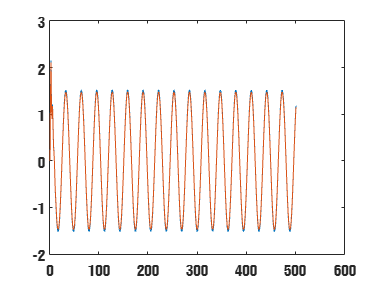

figure;
plot(y(1,:));
hold on;
plot(outEst(1,:));

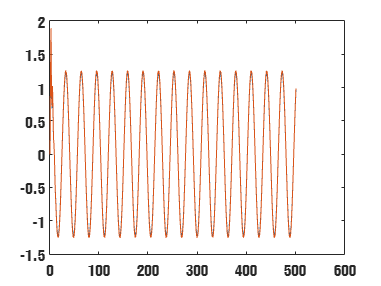

figure;
plot(y(2,:));
hold on;
plot(outEst(2,:));

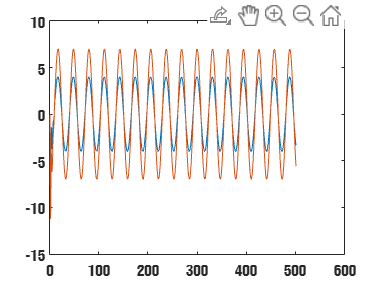

state = info.X{1};
figure;
plot(state(5,:));
hold on;
plot(outEst(7,:));